# Exercises

% F5             - run script 
% ctrl + enter   - run current section
% alt + enter    - shift to code/text
% ctrl + r       - comment
% ctrl + t       - uncomment

## 1 Simultaneous Random Variables

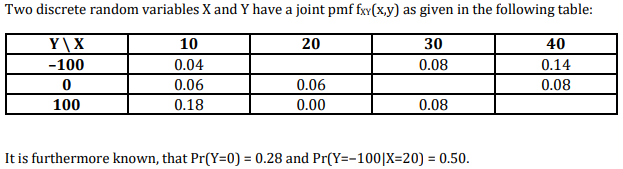

### 1.1 Fill in the empty places in the joint pmf-table.

Y_n_100 = [0.04, nan, 0.08, 0.14];
Y_0 = [0.06, 0.06, nan, 0.08];
Y_100 = [0.18, 0, 0.08, nan];

YX = [Y_n_100; Y_0; Y_100];

syms x

eqn = x == YX(2, 2) + YX(3, 2);

YX(1, 2) = solve(eqn, x);

eqn = 0.28 == YX(2, 1) + YX(2, 2) + YX(2, 4) + x;

YX(2, 3) = solve(eqn, x);

eqn = 1 == sum(YX(1, :)) + sum(YX(2, :)) + sum(YX(3, 1:3)) + x;

YX(3, 4) = solve(eqn, x)

YX =     0.0400    0.0600    0.0800    0.1400
    0.0600    0.0600    0.0800    0.0800
    0.1800         0    0.0800    0.1400



clear x


### 1.2 Calculate and sketch the marginals fX(x) and fY(y).

total_X = [sum(YX(:, 1)), sum(YX(:, 2)), sum(YX(:, 3)), sum(YX(:, 4))]

total_X =     0.2800    0.1200    0.2400    0.3600


total_Y = [sum(YX(1, :)); sum(YX(2,:)); sum(YX(3, :))]

total_Y =     0.3200
    0.2800
    0.4000


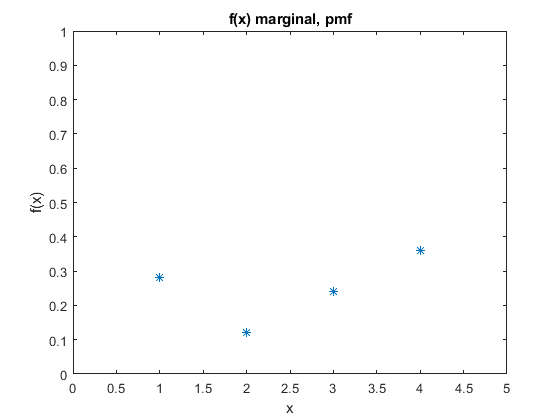


figure(1)
plot(1:4, total_X, "*");
title("f(x) marginal, pmf");
ylim(0:1);
xlim([0 5]);
xlabel('x');
ylabel('f(x)');

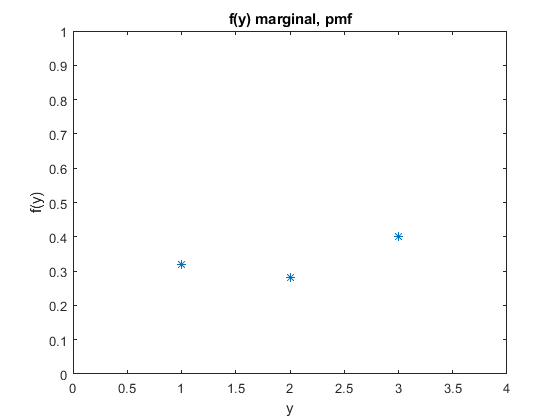

figure(2)
plot(1:3, total_Y, "*");
title("f(y) marginal, pmf");
ylim(0:1);
xlim([0 4]);
xlabel('y');
ylabel('f(y)');

## 2 Data Sampling

## 3 Transformation of Random Variable 

## 4 Multivariate Random Variables 

## 5 The Central Limit Theorem (CLT) 